clc; clear all; close all;

nx = 3; % Número de estados
nu = 2; % Número de entradas
n_f_b = 4;

syms x [3 1]
syms u [2 1]
syms t

A = jacobian(sistema(t, x, u), x);
B = jacobian(sistema(t, x, u), u);

xd = [0; 0; 0];
ud = [0; 0];
A = double(subs(A, [x; u], [xd; ud]));
B = double(subs(B, [x; u], [xd; ud]));

K0 = lqr(A, B, diag([100 1 100]), diag([0.1 0.1]));
z0 = rand(size([K0(:); zeros(nu + nu * n_f_b, 1)]));
options = optimoptions("fmincon", "MaxFunctionEvaluations", 12000);

i = 1;
x0 = [1; 1; 1];

% Verificación de valores iniciales
Jtest = costo(z0, i, x0);
disp("Jtest:"), disp(Jtest);

Jtest:
   5.4651e+04



utest = control(0, x0, z0);
disp("utest:"), disp(utest);

utest:
    1.1815
    1.3957



xtest = sistema(0, x0, utest);
disp("xtest:"), disp(xtest);

xtest:
    1.0000
    0.9930
   -0.6099




[zopt, Jopt] = fmincon(@(z) costo(z, i, x0), z0, [], [], [], [], [], [], @(z) restr(z, A, B), options);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 1.200000e+04.



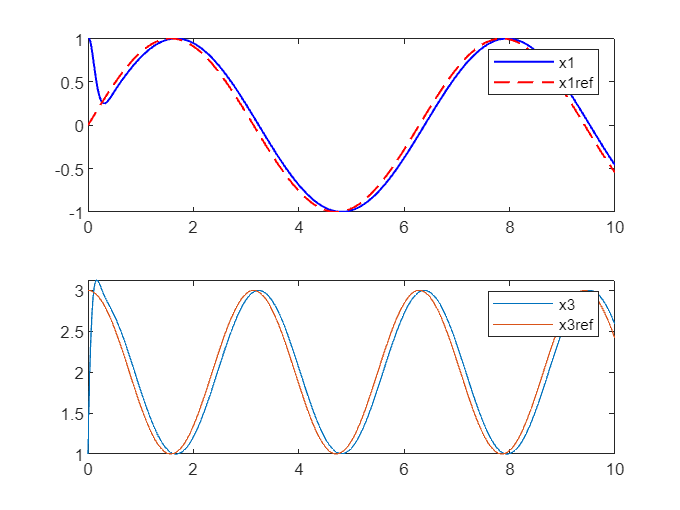


[T, X] = ode45(@(t, x) sistema(t, x, control(t, x, zopt)), [0 10], x0);

figure()
subplot(211)
plot(T, X(:, 1),'b', 'LineWidth', 1); hold on;
plot(T, sin(T),'r--', 'LineWidth', 1);
legend('x1', 'x1ref')

subplot(212)
plot(T, X(:, 3)); hold on;
plot(T, 2 + cos(2 * T));
legend('x3', 'x3ref')

function J = costo(z, i, x0)
    fun = @(t, x) sistema(t, x, control(t, x, z));
    Ts = 0.1;
    T = (0:Ts:6)'; xk = x0;
    U = []; Ye = [];
    for k = 1:length(T)
        U = [U; control(k * Ts, xk, z)];
        k1 = fun(k * Ts, xk);
        k2 = fun(k * Ts + Ts / 2, xk + k1 * Ts / 2);
        k3 = fun(k * Ts + Ts / 2, xk + k2 * Ts / 2);
        k4 = fun(k * Ts + Ts, xk + k3 * Ts);
        xk = xk + Ts * (k1 + 2 * k2 + 2 * k3 + k4) / 6;
        yk = [1 0 0; 0 0 1] * xk;
        t = Ts * k;
        yrefk = [sin(t); 2 + cos(2 * t)];
        Ye = [Ye; yk - yrefk];
    end
    J = sum(abs(Ye)) + 0.0001 * sum((U.^2));
end

function [c, c_eq] = restr(z, A, B)
    nx = 3;
    nu = 2;
    K = reshape(z(1:(nu * nx)), [nu, nx]);
    c = [max(real(eig(A - B * K))) + 0.2];
    c_eq = [];
end

function u = control(t, x, z)
    nx = 3;
    nu = 2;
    n_f_b = 4;
    K = reshape(z(1:(nu * nx)), [nu, nx]);
    K1 = z((nu * nx) + (1:nu));
    K2 = reshape(z(nu * nx + nu + (1:(nu * n_f_b))), [nu, n_f_b]);
    u = -K * x + K1 + K2 * [sin(t); 2 + cos(2 * t); cos(t); -2 * sin(2 * t)];
end

function dx = sistema(t, x, u)
    dx = [
        x(2);
        -0.1 * sin(x(1)) - 0.2 * x(1) - x(1)^3 - 0.3 * x(2) + u(1) + u(2);
        u(1) - 2 * u(2) + x(3)
    ];
end


% % 
% % clc; clear all; close all;
% % 
% % nx = 3; % Número de estados
% % nu = 2; % Número de entradas
% % n_f_b = 4;
% % 
% % syms x [3 1]
% % syms u [2 1]
% % syms t
% % 
% % A = jacobian(sistema(t, x, u), x);
% % B = jacobian(sistema(t, x, u), u);
% % 
% % xd = [0; 0; 0];
% % ud = [0; 0];
% % A = double(subs(A, [x; u], [xd; ud]));
% % B = double(subs(B, [x; u], [xd; ud]));
% % 
% % K0 = lqr(A, B, diag([100 1 100]), diag([0.1 0.1]));
% % z0 = rand(size([K0(:); zeros(nu + nu * n_f_b, 1)]));
% % options = optimoptions("fmincon", "MaxFunctionEvaluations", 12000);
% % 
% % i = 1;
% % x0 = [1; 1; 1];
% % 
% % % Verificación de valores iniciales
% % Jtest = costo(z0, i, x0);
% % disp("Jtest:"), disp(Jtest);
% % utest = control(0, x0, z0);
% % disp("utest:"), disp(utest);
% % xtest = sistema(0, x0, utest);
% % disp("xtest:"), disp(xtest);
% % 
% % [zopt, Jopt] = fmincon(@(z) costo(z, i, x0), z0, [], [], [], [], [], [], @(z) restr(z, A, B), options);
% % 
% % [T, X] = ode45(@(t, x) sistema(t, x, control(t, x, zopt)), [0 10], x0);
% % 
% % figure()
% % subplot(211)
% % plot(T, X(:, 1)); hold on;
% % plot(T, sin(T));
% % legend('x1', 'x1ref')
% % 
% % subplot(212)
% % plot(T, X(:, 3)); hold on;
% % plot(T, 2 + cos(2 * T));
% % legend('x3', 'x3ref')
% % 
% % 
% % function J = costo(z, i, x0)
% %     fun = @(t, x) sistema(t, x, control(t, x, z));
% %     Ts = 0.1;
% %     T = (0:Ts:6)'; xk = x0;
% %     U = []; Ye = [];
% %     for k = 1:length(T)
% %         U = [U; control(k * Ts, xk, z)];
% %         k1 = fun(k * Ts, xk);
% %         k2 = fun(k * Ts + Ts / 2, xk + k1 * Ts / 2);
% %         k3 = fun(k * Ts + Ts / 2, xk + k2 * Ts / 2);
% %         k4 = fun(k * Ts + Ts, xk + k3 * Ts);
% %         xk = xk + Ts * (k1 + 2 * k2 + 2 * k3 + k4) / 6;
% %         yk = [1 0 0; 0 0 1] * xk;
% %         t = Ts * k;
% %         yrefk = [sin(t); 2 + cos(2 * t)];
% %         Ye = [Ye; yk - yrefk];
% %     end
% %     J = sum(abs(Ye)) + 0.0001 * sum((U.^2));
% % end
% % 
% % function [c, c_eq] = restr(z, A, B)
% %     nx = 3;
% %     nu = 2;
% %     K = reshape(z(1:(nu * nx)), [nu, nx]);
% %     c = [max(real(eig(A - B * K))) + 0.2];
% %     c_eq = [];
% % end
% % 
% % function u = control(t, x, z)
% %     nx = 3;
% %     nu = 2;
% %     n_f_b = 4;
% %     K = reshape(z(1:(nu * nx)), [nu, nx]);
% %     K1 = z((nu * nx) + (1:nu));
% %     K2 = reshape(z(nu * nx + nu + (1:(nu * n_f_b))), [nu, n_f_b]);
% %     u = -K * x + K1 + K2 * [sin(t); 2 + cos(2 * t); cos(t); -2 * sin(2 * t)];
% % end
% % 
% % function dx = sistema(t, x, u)
% %     dx = [
% %         x(2);
% %         -0.1 * sin(x(1)) - 0.2 * x(1) - x(1)^3 - 0.3 * x(2) + u(1) + u(2);
% %         u(1) - 2 * u(2) + x(3)
% %     ];
% % end
